# Sample script of SUBBANDSCALINGLAYER

 Copyright (c) Shogo MURAMATSU, 2021

 All rights reserved.


type subbandScalingLayer

classdef subbandScalingLayer < nnet.layer.Layer
    % 
    
    properties
        NumberOfChannels
    end
    
    properties(Learnable)
        % Layer learnable parameters
        Scale
        Bias
    end
    
    methods
        function layer = subbandScalingLayer(varargin) 
            p = inputParser;
            addParameter(p,'Name','')
            addParameter(p,'Scale',1)
            addParameter(p,'Bias',0)
            addParameter(p,'NumberOfChannels',1)
            parse(p,varargin{:})
            
            % Set layer name.
            layer.Name = p.Results.Name;
            layer.NumberOfChannels = p.Results.NumberOfChannels;
            
            % Initialize scaling coefficient.
            layer.Scale = permute(p.Results.Scale.*ones(layer.NumberOfChannels,1),[2 3 1]);            
            layer.Bias = permute(p.Results.Bias.*ones(layer.NumberOfChannels,1),[2 3 1]);            
            
            layer.NumInputs = 1;

            % Set layer descrip

layer = subbandScalingLayer('Name','scaling','Scale',2,'Bias',1)

layer =   subbandScalingLayer のプロパティ:

                Name: 'scaling'
    NumberOfChannels: 1

   学習可能パラメーター
               Scale: 2
                Bias: 1

  すべてのプロパティを表示


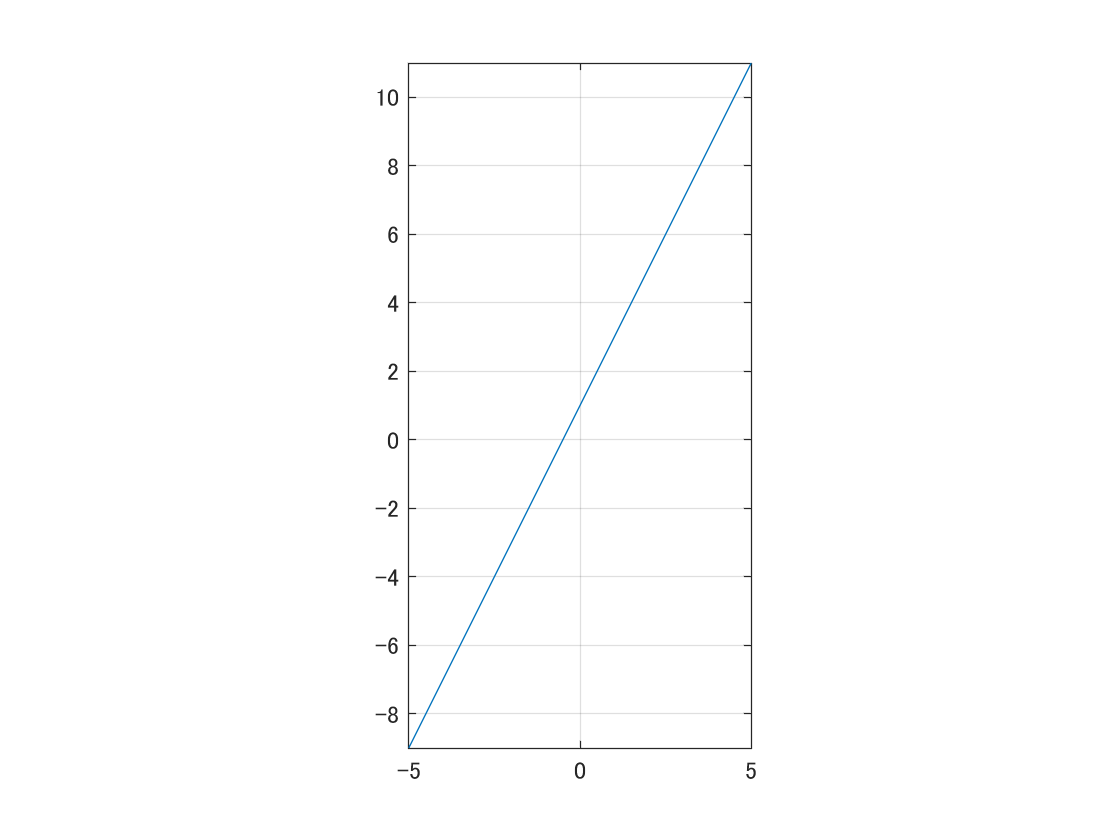


fplot(@(x) extractdata(layer.predict(dlarray(x))))
axis equal
grid on


checkLayer(layer,[24 24 20],'ObservationDimension',4)

コード生成互換性テストをスキップします。コード生成用の層の有効性をチェックするには、'CheckCodegenCompatibility' および 'ObservationDimension' オプションを指定します。
 
nnet.checklayer.TestLayerWithoutBackward を実行しています
.......... .......
nnet.checklayer.TestLayerWithoutBackward が完了しました
__________

テストの概要:
	 17 パス、0 失敗、0 未完了、5 スキップ。
	 経過時間: 0.038387 秒。
